# Creating and Training a CNN to Classify Traffic Signs

For the Week 1 Project, you will:

- Prepare the traffic signs dataset for training

- Create a simple CNN

- Train the model to classify traffic signs

- Evaluate your trained model on test data

After you have finished, please proceed to the **"Project: Classifying Traffic Signs with a Simple CNN" **assessment to answer questions about your results.

## Prepare Your Data for Training

Inside the "Traffic Signs" folder, the data is already separated into Train and Test folders. 

Create an image datastore from the training dataset named `imdsSigns`:

% Select the location of the training data set:
filename = "F:\courses\coursera\Past\Specialization-Mathworks Deeplearning for Computer Vision\Deep Learning for Computer Vision\Data\Traffic Signs\Train";

Use 80% of your data for training, leaving the remaining images for validation. Make sure to randomize which images are assigned to the validation set.

imdsSigns = imageDatastore(filename, "IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsSigns, 0.8, 'randomized');

length(imdsTrain.Files)

ans = 720

%[ncat, ia, ic] = unique(imdsValidation.Labels)
countEachLabel(imdsValidation)

ans = 9×2 table
         Label         Count
    _______________    _____

    End Speed Limit     20  
    Speed Limit 100     20  
    Speed Limit 120     20  
    Speed Limit 20      20  
    Speed Limit 30      20  
    Speed Limit 50      20  
    Speed Limit 60      20  
    Speed Limit 70      20  
    Speed Limit 80      20  


## Preview the Training Data

Before you dive into building your network architecture, it's worth familiarizing yourself with the images in this data set. 

Run this section several times to preview some of the training data:

img = read(imdsSigns);
size(img)

ans =     32    32     3


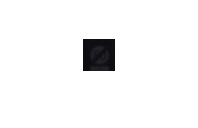

imshow(img)

Notice how many of the images are small, dark, blury, or otherwise difficult to see. 

All images are in RGB format, with sizes  $m \times n \times 3$, but they have a range of different sizes. Before you can train, you will have to resize these images to match the image input layer.

## Define the Network Architecture

Open the Deep Network Designer App to create and export a network with the following layers:

- `imageInputLayer`

- `convolution2dLayer`

- `reluLayer`

- `maxPooling2dLayer`

- `fullyConnectedLayer`

- `softmaxLayer`

- `classificationLayer`

Make sure you specify the correct `OutputSize` for `fullyConnectedLayer`.

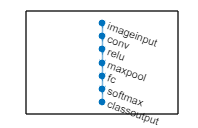

% Insert the code generated from the Deep Network Designer App:
layers = [
    imageInputLayer([32 32 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(9,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
plot(layerGraph(layers));

## Resize Your Training Data

Resize the training and validation data to match the `InputSize` that you set above:

augTrain = augmentedImageDatastore([32,32], imdsTrain);
augValid = augmentedImageDatastore([32,32], imdsValidation);

## Setting the Training Options

Finally, set your training options. You'll investigate training options in more detail later in this course. For now, use the same options as you saw in the video:

- Set the solver to `"adam"`

- Include the validation data you set aside earlier

- Set the Shuffle option to `"every-epoch"`

- Set the Plots option to `"training-progress"`

% Insert code to set the training options:
opts = trainingOptions("adam", "ValidationData", augValid, ...
                "ExecutionEnvironment", "cpu", ...
                "Shuffle", "every-epoch", "Plots", "training-progress");


## Train the Network

It's finally time to train your network! 

% Insert code to train your network:

net = trainNetwork(augTrain, layers, opts);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       17.97% |       11.67% |      55.6050 |     312.2902 |          0.0010 |
|      10 |          50 |       00:01:23 |       50.00% |       41.67% |      17.9647 |      19.2249 |          0.0010 |
|      20 |         100 |       00:02:41 |       90.62% |       63.89% |       0.7976 |       7.7012 |          0.0010 |
|      30 |         150 |       00:04:01 |       92.19% |       58.33% |       0.4832 |       8.5153 |          0.

Training will likely take about 20 minutes using a CPU.

## Performance on Test Data

Once you have trained your network, you should examine its performance on your test data.

Don't forget to resize your images to match the expected input size for your trained network:

filenameTest = "F:\courses\coursera\Past\Specialization-Mathworks Deeplearning for Computer Vision\Deep Learning for Computer Vision\Data\Traffic Signs\Test";
imdsTest = imageDatastore(filenameTest, "IncludeSubfolders",true,"LabelSource","foldernames");
augTest = augmentedImageDatastore([32,32], imdsTest);

Finally, use your test data to evaluate your trained network, including calculating the test accuracy and creating a confusion chart. You may need to click the arrow and open your confusion charts in the figure window to see them well:

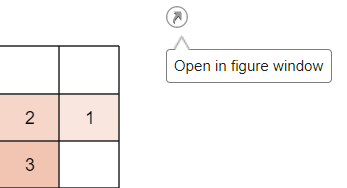

% Classify your test data:
testPreds = classify(net, augTest);

% Compute the test accuracy and create a confusion chart:
testAccuracy = nnz(testPreds == imdsTest.Labels) / length(testPreds)

testAccuracy = 0.6389

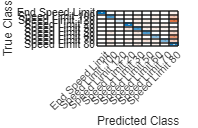

confusionchart(imdsTest.Labels, testPreds)

While not perfect, this network performs surprisingly well considering the limited data set and the relatively simple architecture of your neural network. Later in this course, you will see how to achieve much better accuracy and loss values for this dataset.

Once you have completed this reading, proceed to the "Week 1 Project: Classifying Traffic Signs with a Simple CNN" quiz. You may want to keep this completed live script open as a reference as you answer questions about your results.

*Copyright 2024 The MathWorks, Inc.*